s = tf('s');
g = 9.80665;

% === Cascaded System Transfer Functions ===
G_inner = g/s;   % Velocity → Accel (Roll/Pitch)

% === Design Specs ===
OS_pos = 20;     % Position overshoot (%)
T_s_pos = 10;     % Settling time for position loop (s)
frac = 4;        % Scale

OS_vel = OS_pos/frac;     % Velocity overshoot (%)
T_s_vel = T_s_pos/frac;   % Settling time for velocity loop (s)

% === Inner Loop (Velocity PD) ===
zeta_vel = -log(OS_vel/100)/sqrt(pi^2 + log(OS_vel/100)^2)

zeta_vel = 0.6901

omega_n_vel = 4 / (zeta_vel * T_s_vel)

omega_n_vel = 2.3185

pole_vel = -zeta_vel*omega_n_vel + 1i*omega_n_vel*sqrt(1 - zeta_vel^2)

pole_vel = -1.6000 + 1.6779i

G_at_pole_inner = evalfr(G_inner, pole_vel)

G_at_pole_inner = -2.9190 - 3.0611i

phi_vel = pi - angle(G_at_pole_inner)

phi_vel = 5.4740

z_c_vel = real(pole_vel) + imag(pole_vel) / tan(phi_vel)

z_c_vel = -3.2000

Kd_vel = 1 / abs((pole_vel - z_c_vel) * G_at_pole_inner)

Kd_vel = 0.1020

Kp_vel = Kd_vel * z_c_vel

Kp_vel = -0.3263

D_inner = abs(Kd_vel) * (s + abs(z_c_vel))  % Ensure positive gains


D_inner =
 
  0.102 s + 0.3263
 
Continuous-time transfer function.
Model Properties



Inner_CL = feedback(D_inner * G_inner, 1);

% === Outer Loop (Position PD) ===
G_outer = Inner_CL * 1/s   % Position → Velocity


G_outer =
 
     s + 3.2
  -------------
  2 s^2 + 3.2 s
 
Continuous-time transfer function.
Model Properties



zeta_pos = -log(OS_pos/100)/sqrt(pi^2 + log(OS_pos/100)^2);
omega_n_pos = 4 / (zeta_pos * T_s_pos);
pole_pos = -zeta_pos*omega_n_pos + 1i*omega_n_pos*sqrt(1 - zeta_pos^2);
G_at_pole_outer = evalfr(G_outer, pole_pos);
phi_pos = pi - angle(G_at_pole_outer);
z_c_pos = real(pole_pos) + imag(pole_pos) / tan(phi_pos);
Kd_pos = 1 / abs((pole_pos - z_c_pos) * G_at_pole_outer)

Kd_pos = 0.7881

Kp_pos = Kd_pos * z_c_pos

Kp_pos = -0.9220

D_outer = abs(Kd_pos) * (s + abs(z_c_pos))  % Ensure positive gains


D_outer =
 
  0.7881 s + 0.922
 
Continuous-time transfer function.
Model Properties



Outer_CL = feedback(D_outer * G_outer, 1)  % Full position loop closed


Outer_CL =
 
  0.7881 s^2 + 3.444 s + 2.95
  ---------------------------
  2.788 s^2 + 6.644 s + 2.95
 
Continuous-time transfer function.
Model Properties


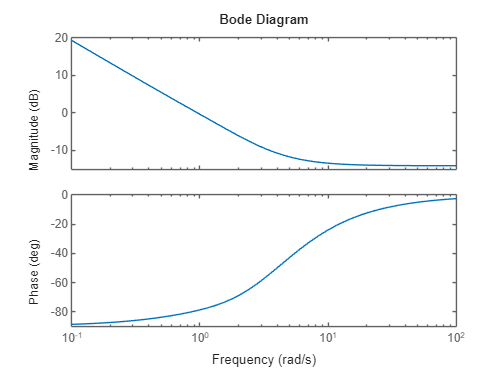


% Bodeplot of systems
%outer
bode(D_outer * G_outer * Inner_CL);

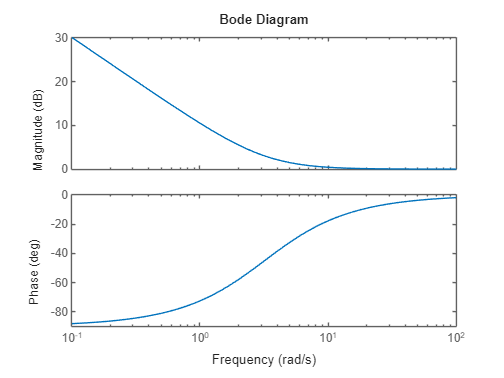

%Inner
bode(D_inner * G_inner);

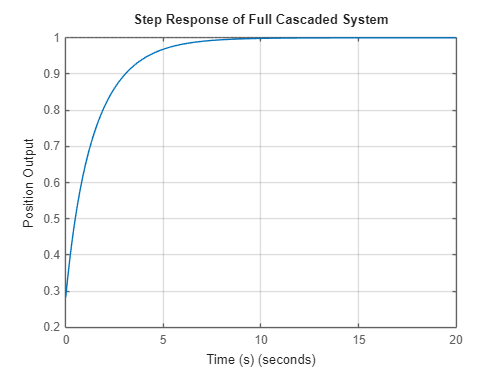


% === Check Stability ===
poles_outer = pole(Outer_CL);
if max(real(poles_outer)) >= 0
    fprintf('Warning: The outer loop is unstable.\n');
end

% === Plot Step Response ===
figure;
step(Outer_CL, 20);  % Increase simulation time
title('Step Response of Full Cascaded System');
xlabel('Time (s)');
ylabel('Position Output');
grid on;


% === Step Info Summary ===
step_info = stepinfo(Outer_CL);

% === Display Gains ===
fprintf('\n--- Controller Gains ---\n');


--- Controller Gains ---


fprintf('Outer loop (Position → Velocity):  Kp = %.4f, Kd = %.4f\n', abs(Kp_pos), abs(Kd_pos));

Outer loop (Position → Velocity):  Kp = 0.9220, Kd = 0.7881


fprintf('Inner loop (Velocity → Roll/Pitch):  Kp = %.4f, Kd = %.4f\n', abs(Kp_vel), abs(Kd_vel));

Inner loop (Velocity → Roll/Pitch):  Kp = 0.3263, Kd = 0.1020
